# Analogia entre vetores e sinais

## Definindo variáveis

syms n t
T0 = 1;
f0 = 1/T0;
w0 = 2*pi*f0;
N = 10;
NN = N+1;
n = [-N:1:N];
R = T0/1000;
tempo = [0:R:T0];
aux = 0;
pnn = 0;
rntotal = 0;

## Definindo funções

gt = @(t) (exp(-t));
gn = @(t) (exp(-1i*n*w0*t));
cn = (1/T0)*(int((gt(t)*gn(t)), t, 0, T0))

$$cn = \begin{array}{l} \left(\begin{array}{ccccccccccccccccccccc} -\frac{\sigma_{2}}{-1+20\,\pi \,\mathrm{i}} & -\frac{\sigma_{2}}{-1+18\,\pi \,\mathrm{i}} & -\frac{\sigma_{2}}{-1+16\,\pi \,\mathrm{i}} & -\frac{\sigma_{2}}{-1+14\,\pi \,\mathrm{i}} & -\frac{\sigma_{2}}{-1+12\,\pi \,\mathrm{i}} & -\frac{\sigma_{2}}{-1+10\,\pi \,\mathrm{i}} & -\frac{\sigma_{2}}{-1+8\,\pi \,\mathrm{i}} & -\frac{\sigma_{2}}{-1+6\,\pi \,\mathrm{i}} & -\frac{\sigma_{2}}{-1+4\,\pi \,\mathrm{i}} & -\frac{\sigma_{2}}{-1+2\,\pi \,\mathrm{i}} & 1-{\mathrm{e}}^{-1} & -\frac{\sigma_{1}}{2\,\pi -\mathrm{i}} & -\frac{\sigma_{1}}{4\,\pi -\mathrm{i}} & -\frac{\sigma_{1}}{6\,\pi -\mathrm{i}} & -\frac{\sigma_{1}}{8\,\pi -\mathrm{i}} & -\frac{\sigma_{1}}{10\,\pi -\mathrm{i}} & -\frac{\sigma_{1}}{12\,\pi -\mathrm{i}} & -\frac{\sigma_{1}}{14\,\pi -\mathrm{i}} & -\frac{\sigma_{1}}{16\,\pi -\mathrm{i}} & -\frac{\sigma_{1}}{18\,\pi -\mathrm{i}} & -\frac{\sigma_{1}}{20\,\pi -\mathrm{i}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}\\ \sigma_{2}={\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right) \end{array}$$

C = eval(cn)

C =    0.0002 + 0.0101i   0.0002 + 0.0112i   0.0003 + 0.0126i   0.0003 + 0.0144i   0.0004 + 0.0168i   0.0006 + 0.0201i   0.0010 + 0.0251i   0.0018 + 0.0334i   0.0040 + 0.0500i   0.0156 + 0.0981i   0.6321 + 0.0000i   0.0156 - 0.0981i   0.0040 - 0.0500i   0.0018 - 0.0334i   0.0010 - 0.0251i   0.0006 - 0.0201i   0.0004 - 0.0168i   0.0003 - 0.0144i   0.0003 - 0.0126i   0.0002 - 0.0112i   0.0002 - 0.0101i


%pn = @(t) (cn * exp(-1i*n*wo*t)) + (c(-n) * exp(-1i*n*wo*t));
%rn = @(t) gt - (pn(t)+p(n+1));

## Sintetizando o Sinal

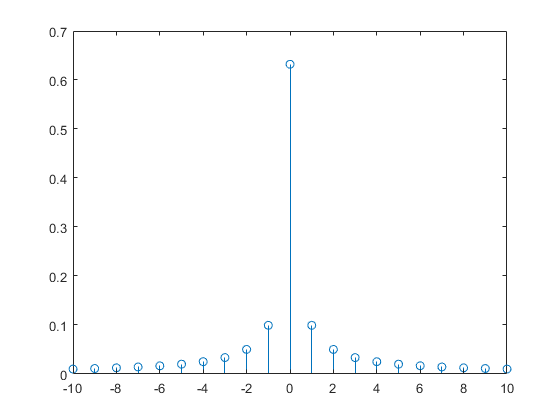

for k=1:2*N+1
    aux = aux + cn(k)*exp(1i*n(k)*w0*tempo);
end
pn = aux;

for k=1:N
    pnn = pnn + C(NN+k) * exp(i*n(NN+k)*w0*tempo) + C(NN-k) * exp(i*n(NN-k)*w0*tempo);
end

rntotal = gt(tempo) - pnn;

figure()
stem(n*f0, abs(eval(cn)));

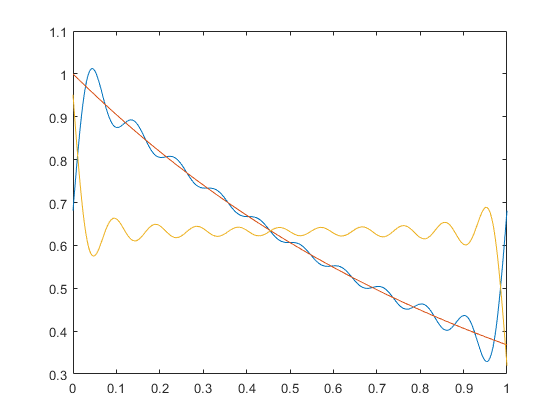

plot(tempo, aux, tempo, gt(tempo), tempo, rntotal(end,:));